# **Estimating battery state of charge using recurrent and non-recurrent neural networks**

## The objective of this code is to present the training process of a battery State-of-Charge (SOC) estimator using  **recurrent (LSTM) and** **non-recurrent neural network** (FNN) approach. 

**Abstract**

Battery state of charge estimation is critical for determining the remaining range of electrified vehicles and the runtime of battery-powered equipment. Neural network algorithms which learn the relation between battery measurements and state of charge are a promising alternative to estimators based on models with adaptive filters. In this work, two types of neural networks are studied: recurrent networks, which have inherent memory of the past, and non-recurrent networks, which can effectively have memory added through exogenous filtered inputs. An extensive and comprehensive study is performed for these network types, with learnable parameters ranging from 20 to 3000. Network performance is compared for two different battery types, multiple temperatures, drive cycles, and training repetitions. Compared to a recurrent neural network, a non-recurrent feedforward neural network with filtered inputs is found to be up to 23% more accurate, require less training time (76% less using a CPU and 60% less using a GPU), and execute in about 1/3 the amount of time on an NXP S32K142 microprocessor.

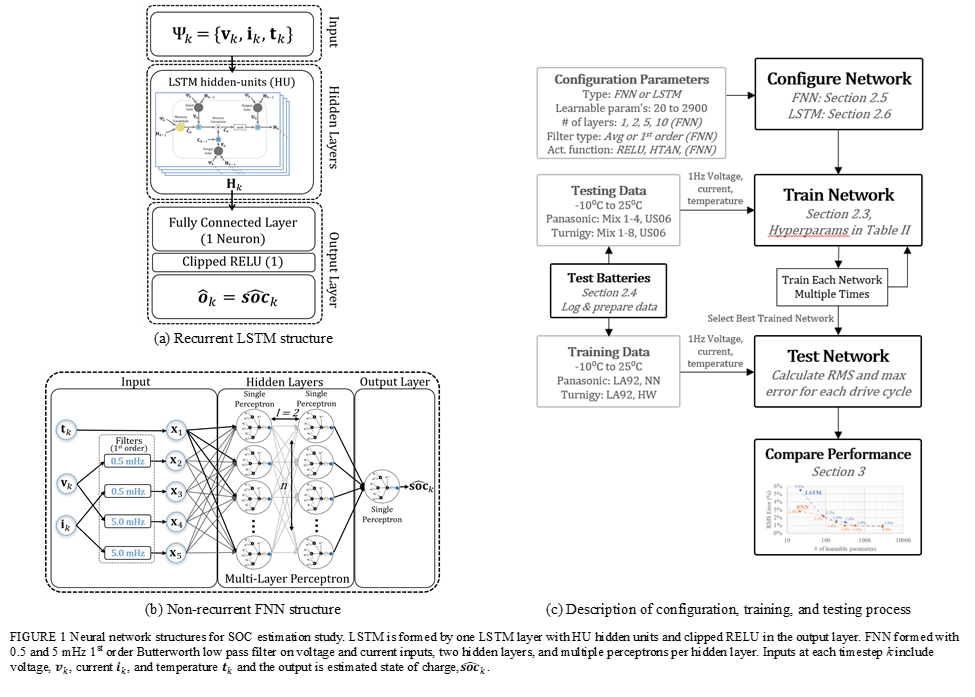

close all;
clearvars;
fclose all;

**Add the Dataset File name**

If you want to use a different data file, replace "**FileName.zip**" by the file name you want to use. Note: The zip file need to have "**Train**"  and "**Test**" separate folders

filename ="Panasonic_NCR18650PF_Data_Normalized.zip"; % Add the Dataset File name
outputFolder = fullfile(tempdir,"Panasonic");% The temporary location and name where the training data unzipped
unzip(filename,outputFolder); 
Test_Files = fullfile(outputFolder,"Test","Test.mat");
load (Test_Files,"X_Test","Y_Test");

**Add the location** in ('...') where the data of each iteration will be stored as it will save multiple models at each epoch (see"CheckpointPath" on the training parameter);

mkdir("TrainedModelsFolder_1");
mkdir("TrainedModelsFolder_2");% 
NET_Path=[];
%slect the Datafolder created in the next popup window to allow storing the
%the data each iteration
NET_Path{1}=uigetdir('','Select folder to store data from each training iteration for Trial #1'); 
NET_Path{2}=uigetdir('','Select folder to store data from each training iteration for Trial #2'); 

For the training predictors, create a file datastore and specify the read function to be the `load` function. The `load` function, loads the data from the MAT-file into a structure array. To read files from the subfolders in the training folder, set the `'IncludeSubfolders'` option to `true`.

NumberOfTrainingFolders = 1;%set here the number of cases or folders to be used to train the NN separately 
for l=1:NumberOfTrainingFolders
File = num2str(l);% Loop on each Folder
folderTrain = fullfile(outputFolder,"Train",File);
fds_X_Train = fileDatastore(folderTrain, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true);
folderTest = fullfile(outputFolder,"Test");
fds_X_Test = fileDatastore(folderTest, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true);

## VALIDATION DATASET - DATASTORAGE - TRANSFORMATION

folderValidation  =   fullfile(outputFolder,"Validation");

fds_X_Validation = fileDatastore(folderValidation, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true);
fds_Y_Validation = fileDatastore(folderValidation, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true);

VV=readall(fds_X_Validation);
numObservations = numel(VV);
for i=1:numObservations
    sequence = VV{i};
    sequenceLength_Validation(i) = size(sequence.X,2);
end
tds_X_Validation = transform(fds_X_Validation,@(data) padSequence(data,sequenceLength_Validation));
tds_Y_Validation = transform(fds_Y_Validation,@(data) padSequenceY(data,sequenceLength_Validation));
preview(tds_X_Validation);
% 
folder_Y_Train = fullfile(outputFolder,"Train",File);
fds_Y_Train = fileDatastore(folder_Y_Train, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true);

folder_Y_Test = fullfile(outputFolder,"Test");
fds_Y_Test = fileDatastore(folder_Y_Test, ...
    'ReadFcn',@load, ...
    'IncludeSubfolders',true);

Preview the datastore. The output corresponds to the label of the first file.

% preview(fds_Y_Train)
% preview(fds_Y_Test)

# Transform and Combine Datastores

AugmentedData=1;
NumberOfMiniBatches =  1;

RR=readall(fds_X_Train);
numObservations = numel(RR);
for i=1:numObservations
    sequence = RR{i};
    sequenceLengths(i) = size(sequence.X,2);
end

miniBatchSize = round(numObservations/NumberOfMiniBatches)

miniBatchSize = 1

sequenceLength = max(sequenceLengths);
sequenceLength=round(sequenceLength*AugmentedData);

RRR=readall(fds_X_Test);
numObservationsY = numel(RRR);
for i=1:numObservationsY
    sequence = RRR{i};
    sequenceLengthsY(i) = size(sequence.X_Test,2);
end
sequenceLengthY= max(sequenceLengthsY);

tds_Y_Train = transform(fds_Y_Train,@(data) padSequenceY(data,sequenceLength));
tds_Y_Test = transform(fds_Y_Test,@(data) padSequenceY(data,sequenceLengthY));

tds_X_Train = transform(fds_X_Train,@(data) padSequence(data,sequenceLength));
tds_X_Test = transform(fds_X_Test,@(data) padSequence(data,sequenceLengthY));

cdsTrain = combine(tds_X_Train,tds_Y_Train);
cdsTest = combine(tds_X_Test,tds_Y_Test);
cdsVal = combine(tds_X_Validation,tds_Y_Validation);
% preview(cdsTrain)

## Design Recommendations and Conclusions for FNN and LSTM

# 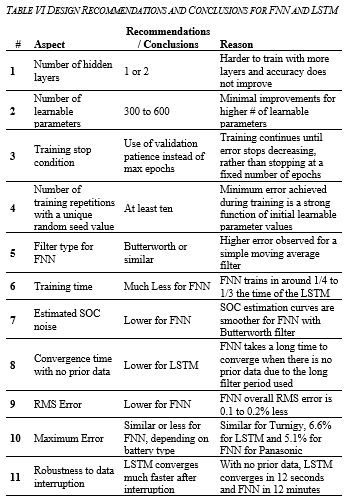

# Specify NN training parameter. 

numResponses = 1;  % number of output expected from the NN, in this case the output is SOC
Epochs  =   10; % maximum number of epochs, after reaching this value the training will stop
LearnRateDropPeriod = 2000;
InitialLearnRate=0.01;%initial Learning rate value
LearnRateDropFactor=0.85; % after each "LearnRateDropPeriod", the learning will be multiplied by "LearnRateDropFactor" number
validationFrequency = 3;% after this number of iterations, the validation dataset will be presented for evaluation during the training process. 
Patience = 12300;
Repetitions =length(NET_Path); % number of times the training process will restart, in the article is refered the number of "trial" or "training repetitions". 
% To train more than #2 will be necessary to create "TrainedModelsFolder"and add extra "NET_Path" (see lines 10 t 16 if the scrript).
NN_Features{1} = 3;
NN_Features{2} = 5;

# Select Neural Network Type: 

### LSTM: NN_Type = 1, (numFeatures = 3)

### FNN: NN_Type = 2, (numFeatures = 5) 

NN_Type = 1;% also need to go to line 237 and make the same choice of NN_Type.

**IMPORTANT**:  go to **"Define Output Function"** at line 237 of the script  **Select Neural Network Type.**

numFeatures = NN_Features{NN_Type};

## Recurrent LSTM Neural Network Structure and Recurrent LSTM Layer graphical representation

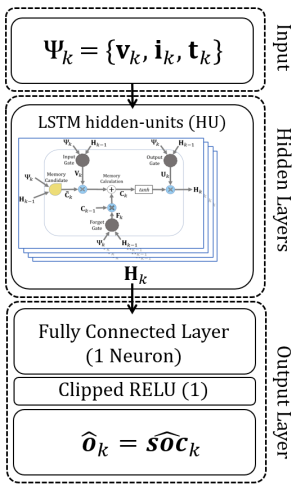                                           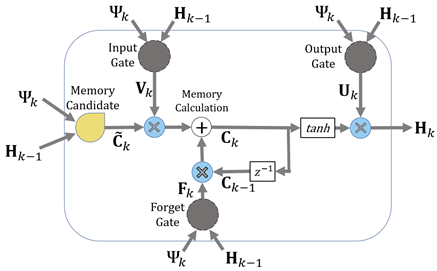

                                           Recurrent LSTM Neural Network Structure                                                            Recurrent LSTM Layer graphical representation

    Note: This example of recurrent LSTM Neural Network Structurehas 571 (#600)  Learnable Parameters

 layers_LSTM = [sequenceInputLayer(numFeatures)
    lstmLayer(10,'OutputMode','sequence') % number of hidden units in this example is '10'
    fullyConnectedLayer(numResponses)
    clippedReluLayer(1)
    regressionLayer];

## FNN Neural Network Structure and Single Perceptron

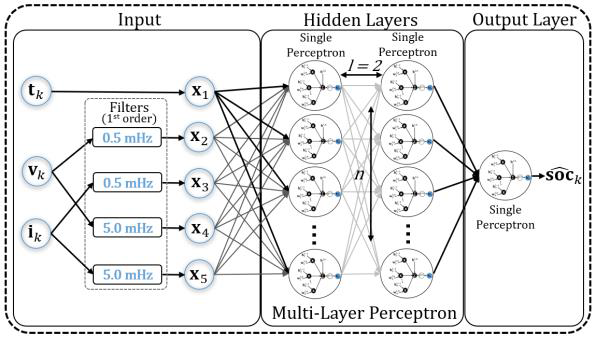                                         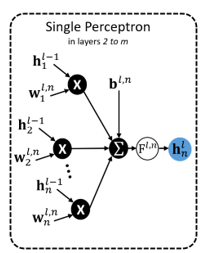

          FNN: Non-recurrent Neural Network Structure                                                                                          Single perceptron

Note: This example has 564 (#600)  Learnable Parameters

layers_FNN = [sequenceInputLayer(numFeatures)
    fullyConnectedLayer(21) % number of hidden units in this example is '21'
    reluLayer
    fullyConnectedLayer(19) % number of hidden units in this example is '19'
    reluLayer
    fullyConnectedLayer(numResponses)
    reluLayer
    regressionLayer];


layers{1} = layers_LSTM;
layers{2} = layers_FNN;
NET=layers{NN_Type};

tic
 for i=1:Repetitions
    G=i;
    Path = NET_Path{i};
    options = trainingOptions('adam', ...
    'MaxEpochs',Epochs,'ExecutionEnvironment','auto', ...
    'GradientThreshold',1, ...
    'InitialLearnRate',InitialLearnRate, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',LearnRateDropPeriod, ...
    'LearnRateDropFactor',LearnRateDropFactor, ...
    'L2Regularization',1, ...
    'Shuffle','never',...
    'ValidationData', cdsVal, ...
    'ValidationFrequency',validationFrequency, ...
    'ValidationPatience',Patience,...
    "Verbose",1,...
    'MiniBatchSize',miniBatchSize, ...
    'OutputFcn',@(info)stopIfAccuracyNotImproving(info,Patience,G),...
    'Plots','training-progress',... %TIP: for faster training process, remove this part. 
    'CheckpointPath', Path);
    tic
    

## ***Training time and microprocessor execution time and Time-domain performance***

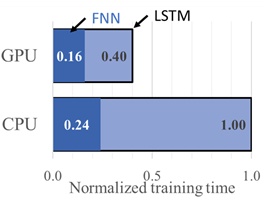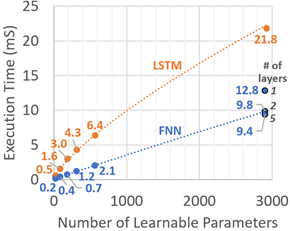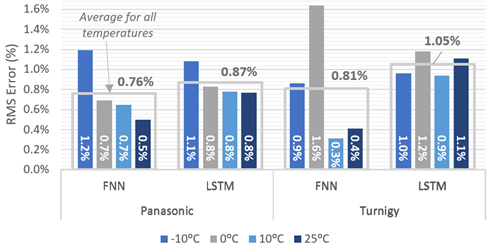

Training time, real-time execution time, and performance of best 600 parameter network. (a) Normalized training time based on FNN and LSTM trained for 50000 epochs, using 3.30GHz Intel Core I7-3960 CPU and NVIDIA GeForceGTX 1080 TI GPU. (b) Time to execute neural network on NXP S32K142 32-bit 80MHz automotive microprocessor. (c) RMS error versus temperature for the best training trial for the approximately 600 parameter FNN and LSTM SOC estimation algorithms.  RMS error for each temperature is the average of the error for the two testing cycles.

It is recommended to use GPUs instead o CPU to train the models, since GPU tend to be faster than CPUs as shown in the figure above or in Figure 12 (a) of the article. In this script it is set to automaticaly select GPU (**'*****auto'****) *if one is availble, otherwise will use a CPU to train the Neural Network. Please, check the triaining ***options*** above or Matlab documentation for further information.

    [net,info] = trainNetwork(cdsTrain,NET,options);
    TrainingTime{i} =toc
    NETS{i} = net;
    INFO{i} = info;
     
    Update=100;
    
   for ii=1:length(Y_Test)
     
    Test{1} = X_Test{2,ii}(1:3,:); % LSTM
    Test{2} = X_Test{2,ii}(3:7,:); % FNN

    updatedNet = predictAndUpdateState(NETS{i},Test{NN_Type}(:,1:Update));
    Prediction_Test =   predict(updatedNet,Test{NN_Type}(:,Update:end),'MiniBatchSize',miniBatchSize);
    Error_Test = (Prediction_Test)-(Y_Test{2,ii}(:,Update:end));
     
    RMSE{ii} = sqrt(mean((Error_Test).^2))*100;
    MAE{ii} = mae(Error_Test)*100;
    Max{ii} = max(abs(Error_Test)*100);
    STDDEV{ii} = std(Error_Test)*100;
    Name{ii} = Y_Test{1,ii};
    Input{ii} =  X_Test{2,ii};
    Objective{ii} = Y_Test{2,ii};
    Error{ii} =  Error_Test;
    NET1{ii} = NETS{i};
  
   end 
    Results{i} = [Name;RMSE;MAE;Max;STDDEV;NET1;Input;Objective;Error];
         

### To plot the result from LA92 at -10degC set **"Selected = 11"**

**Different values of selected will choose other testing drive cycles, see X_test *

    Selected = 11;  

Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:08 |         0.63 |         0.69 |       0.1960 |       0.2347 |          0.0100 |


|       1 |           3 |       00:00:15 |         0.60 |         0.69 |       0.1804 |       0.2383 |          0.0100 |


|       1 |           6 |       00:00:23 |         0.59 |         0.69 |       0.1741 |       0.2413 |          0.0100 |


|       1 |           9 |       00:00:28 |         0.64 |         0.59 |       0.2044 |       0.1744 |          0.0100 |


|       2 |          12 |       00:00:36 |         0.51 |         0.35 |       0.1312 |       0.0597 |          0.0100 |


|       2 |          14 |       00:00:39 |         0.27 |              |       0.0368 |              |          0.0100 |
|======================================================================================================================|


TrainingTime = 1×1 cell array
    {[53.4674]}


Training on single CPU.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:16 |         0.30 |         0.22 |       0.0442 |       0.0239 |          0.0100 |


|       3 |           3 |       00:00:29 |         0.25 |         0.22 |       0.0322 |       0.0239 |          0.0100 |


|       6 |           6 |       00:00:49 |         0.20 |         0.15 |       0.0201 |       0.0115 |          0.0100 |


|       9 |           9 |       00:01:08 |         0.16 |         0.12 |       0.0120 |       0.0073 |          0.0100 |


|      10 |          10 |       00:01:14 |         0.15 |         0.12 |       0.0110 |       0.0078 |          0.0100 |
|======================================================================================================================|


TrainingTime = 1×2 cell array
    {[101.0135]}    {[90.1830]}


    Test{1} = X_Test{2,Selected}(1:3,:); % LSTM
    Test{2} = X_Test{2,Selected}(3:7,:); % FNN
    [updatedNet,Pr] = predictAndUpdateState(NETS{i},Test{NN_Type}(:,1:Update));
    Prediction_Test =   predict(updatedNet,Test{NN_Type}(:,Update:end),'MiniBatchSize',miniBatchSize);
    Error_Test = (Prediction_Test)-(Y_Test{2,Selected}(:,Update:end));
    Pred_1 = Prediction_Test;
    Error_1 = Error_Test;
    Y = Y_Test{2,Selected}(:,Update:end);
    
    e1=round(rms(Error_1*100),2);
    MAX1 = round(Max{Selected},2);
    

### **Plotting the time-domain result from "Selected" drive cycle**

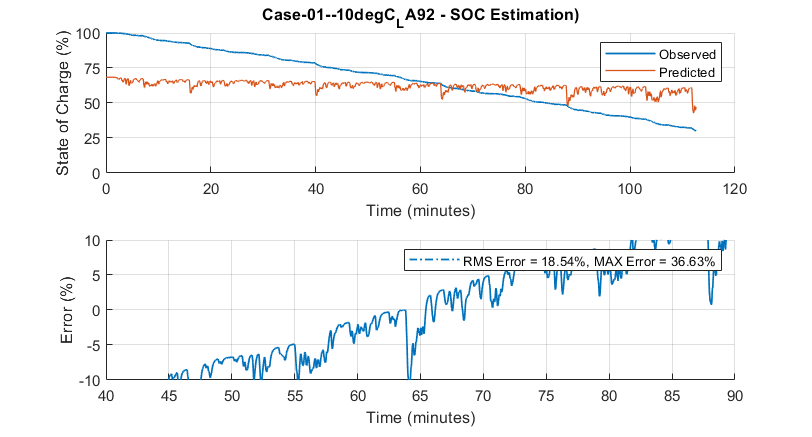

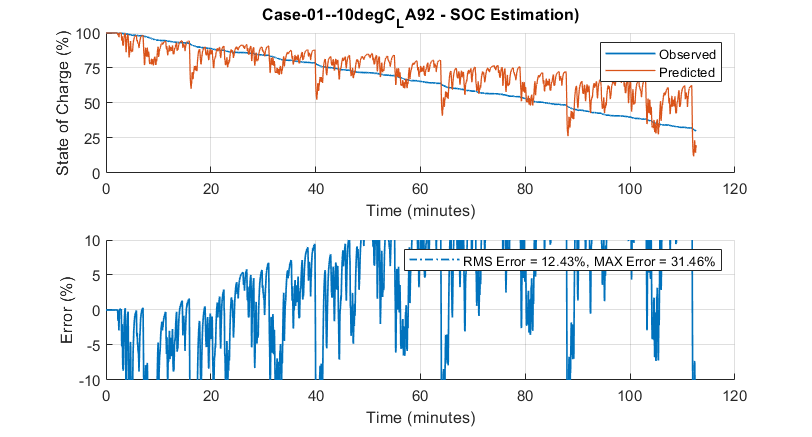

    figure
    subplot(2,1,1)

    grid on
    hold all;
    time = 0:1:(length(Error_1)-1);
    time = time/60;
    plot(time,Y*100,'LineWidth',1,'LineStyle','-','Color','[0 0.4470 0.7410]');
    plot(time,Pred_1*100,'LineWidth',0.75,'LineStyle','-','Color','[0.8500 0.3250 0.0980]');
    legend(["Observed" "Predicted "],'FontSize',8);
    ylabel("State of Charge (%)")
    xlabel('Time (minutes)')
    ylim([0 100])
    yticks([0 25 50 75 100])
    set(gca,'FontSize',9)
    title(['Case-','0',num2str(l),'-', X_Test{1,Selected},' - SOC Estimation)'])
    grid on
    subplot(2,1,2)
    grid on
    hold all;
    plot(time,rms(Error_1*100)*ones(length(Error_1),1),'LineWidth',1,'LineStyle','-.','Color','[0 0.4470 0.7410]')
    plot(time,Error_1*100,'LineWidth',1,'LineStyle','-','Color','[0 0.4470 0.7410]');
    legend(['RMS Error = ',num2str(e1),'%, MAX Error = ',num2str(MAX1),'%'], 'NumColumns',2,'FontSize',8)
    ylabel("Error (%)")
    xlabel('Time (minutes)')
    ylim([-10 10])
    yticks([-10 -5 0 5 10])
    set(gca,'FontSize',9)
    set(gcf,'position',[500,500,650,350])
     
 end    

    Date = char(datetime(floor(now),'ConvertFrom','datenum')); 
    filename = sprintf('Results_SOC_Estimation_');
    FileName=[filename,'_',num2str(i),'#_Trials_' ,Date,'.mat'];  
    save(FileName, 'Results','INFO', 'TrainingTime');%
    
 end


# **Functions**

#### Padding

function sequence = padSequence(data,sequenceLength)

sequence = data.X;
[C,S] = size(sequence);

if S < sequenceLength
    N=round((sequenceLength/S)*1);
    Pad=repmat(sequence,1,N);
   
    padding = Pad(:,1:sequenceLength-S);
    sequence = [sequence padding];
else
    
    sequence = sequence(:,1:sequenceLength);
end

#  **Selected Neural Network Type**

NN_Type = 1;% Selected Neural Network Type

**IMPORTANT**:   Select Neural Network Type above, where **(1) LSTM** and **(2) FNN.**

Type_Features{1} = sequence(1:3,:);%% %% To Train a LSTM with 3 features
Type_Features{2} = sequence(3:7,:);%% To Train a FNN with 5 features;;
sequence = Type_Features{NN_Type};
sequence = {sequence};

end

function sequenceY = padSequenceY(data,sequenceLength)

sequenceY = data.Y;
[C,S] = size(sequenceY);

if S < sequenceLength
    N=round((sequenceLength/S)*1);
    Pad=repmat(sequenceY,1,N);
    padding = Pad(:,1:sequenceLength-S);
    sequenceY = [sequenceY padding];
else
    sequenceY = sequenceY(:,1:sequenceLength);
end

sequenceY = {sequenceY};

end

## Define Output Function

function stop  = stopIfAccuracyNotImproving(info,P,T)


stop = false;


persistent bestValRMSE
persistent valLag
persistent bestIteration

% It clears the variables when training starts.

if info.State == "start"
    bestValRMSE = 10000;
    valLag = 0;
     
elseif ~isempty(info.ValidationRMSE)
    
    if round(info.ValidationRMSE*100,3) <= round(bestValRMSE,3)
        
        valLag = 0;
        bestValRMSE = round(info.ValidationRMSE*100,3);
        bestIteration = info.Iteration;
        
    else
        valLag = valLag + 1;
    end
     
    if valLag >= P % If the model doesn't improve after 'patience' number of iterations
        
        stop = true;
    end
    
    if isempty(bestValRMSE)
        bestValRMSE=10000;
        valLag = 2000;
    end
    
end

end
